dist_to_detector = 2

dist_to_detector = 2

detector_size = 5e-4

detector_size = 5.0000e-04

my_array = voxel_array(zeros(3, 1), 0.25, 0.25, 0.25, 1e-4)

my_array =   voxel_array with properties:

    array_position: [3×1 double]
        num_planes: [3×1 double]
        dimensions: [3×1 double]


ray_fan_angle = pi/8;
num_xrays_per_angle = 2e5;
total_rotation = pi

total_rotation = 3.1416

num_scan_angles = 180

num_scan_angles = 180

source_position = [0; -1; 0];

source_rot_mat = zrot(total_rotation/num_scan_angles)

source_rot_mat =     0.9998   -0.0175         0
    0.0175    0.9998         0
         0         0    1.0000


to_ray_start_mat = zrot(-ray_fan_angle/2)

to_ray_start_mat =     0.9808    0.1951         0
   -0.1951    0.9808         0
         0         0    1.0000


ray_rot_mat = zrot(ray_fan_angle / num_xrays_per_angle)

ray_rot_mat =     1.0000   -0.0000         0
    0.0000    1.0000         0
         0         0    1.0000



num_detectors = ceil(dist_to_detector * ray_fan_angle / detector_size)

num_detectors = 1571

my_detector = detector(source_position.*-1, dist_to_detector, ray_fan_angle, detector_size);
my_ray = ray(zeros(3, 1), zeros(3,1), dist_to_detector); %Slow!
image = zeros(num_detectors, num_scan_angles);
tic
for angle = 1:num_scan_angles+1
    % Get the unit vector from source to detector
    vec_to_detector = source_position.*-1;
    vec_to_detector = vec_to_detector ./ sum(vec_to_detector .^ 2);% pointless for now
    
    % Move the initial directions of detector and rays
    my_detector = my_detector.move_detector(vec_to_detector);
    ray_direction = my_detector.vec_to_detector;

    %Initalise arrays
    mu_array = zeros(1, num_detectors);
    num_hits = zeros(1, num_detectors);

    %Start looping through rays at angle
    for iray = 1:num_xrays_per_angle
        % Update ray and do the ray_tracing
        my_ray = my_ray.update_parameters(source_position, ray_direction);        
        mu = my_ray.calculate_mu(my_array); %Slow! 
        
        % Collate tracing results
        hit_pixel = my_detector.get_hit_pixel(my_ray.direction);
        mu_array(hit_pixel) = mu_array(hit_pixel) + mu;
        num_hits(hit_pixel) = num_hits(hit_pixel) + my_ray.energy;
        
        %Rotate ray around
        ray_direction = ray_rot_mat * ray_direction;
    end
    % Calculate image number
    image(:, angle) = num_hits .* exp(-mu_array);

    %Rotate the source around
    source_position = source_rot_mat * source_position;
end
toc

Elapsed time is 6234.914374 seconds.


image

image =    128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128
   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127
   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127
   128   128   128   128   128   128   128   128   128   128   128   128   128   128   12

image

image =    128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128
   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127
   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127
   128   128   128   128   128   128   128   128   128   128   128   128   128   128   12

I = mat2gray(image)

I =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    0.9922    0.9922    0.9922    0.9922    0.9922    0.9922    0.9922    0.9922    0.9922    0.9922    0.9922    0.9922    0.9922    0.9922    0.9922    0.9922    0.9922    0.9922    0.9922    0.9922    0.9922    0.9922    0.9922    0.9922    0.9922    0.9922    0.9922    0.9922    0.9922    0.9922    0.9922    0.9922    0.9922    0.9922    0.9922    0.9922    0.9922    0.9922    0.9922    0.9922    0.9922    0.9922    0.9922    0.9922    0.9922    0.9922    0.9922    0.9922    0.9922    0


scan_angles = linspace(0, total_rotation, num_scan_angles+1)

scan_angles =          0    0.0175    0.0349    0.0524    0.0698    0.0873    0.1047    0.1222    0.1396    0.1571    0.1745    0.1920    0.2094    0.2269    0.2443    0.2618    0.2793    0.2967    0.3142    0.3316    0.3491    0.3665    0.3840    0.4014    0.4189    0.4363    0.4538    0.4712    0.4887    0.5061    0.5236    0.5411    0.5585    0.5760    0.5934    0.6109    0.6283    0.6458    0.6632    0.6807    0.6981    0.7156    0.7330    0.7505    0.7679    0.7854    0.8029    0.8203    0.8378    0.8552


R = iradon(image, scan_angles)

R =    -0.2080   -0.2376    0.0177    0.0448   -0.1062    0.1889   -0.0183   -0.2315   -0.3620   -0.1576   -0.0792    0.1091    0.0207   -0.0363    0.3568   -0.4475   -0.4166   -0.1759   -0.0917   -0.0338    0.1473    0.3841   -0.5821   -0.1956   -0.1513   -0.3027   -0.1760   -0.0701   -0.0110    0.2950   -0.1268   -0.5076   -0.2569   -0.0262   -0.2264   -0.2659   -0.0294   -0.1690   -0.2848    0.0327   -0.3901   -0.2396   -0.1820   -0.1379   -0.0430   -0.0638   -0.3387   -0.1616   -0.1029   -0.0021
   -0.2139   -0.2393    0.0153    0.0447   -0.1117    0.1907   -0.0037   -0.2363   -0.3651   -0.1581   -0.0804    0.1071    0.0197   -0.0404    0.3639   -0.4376   -0.4234   -0.1780   -0.0919   -0.0352    0.1458    0.3770   -0.5647   -0.2090   -0.1387   -0.3068   -0.1777   -0.0717   -0.0114    0.2869   -0.1091   -0.5151   -0.2576   -0.0336   -0.2103   -0.2730   -0.0301   -0.1685   -0.2858    0.0330   -0.3904   -0.2399   -0.1821   -0.1381   -0.0437   -0.0625   -0.3393   -0.1617   -0.1035   -0

%F = fan2para(I,1/detector_size, FanRotationIncrement=0.5, FanSensorSpacing=my_detector.pixel_angle)
my_detector.pixel_angle

ans = 2.5000e-04

F = ifanbeam(image, 1/detector_size, FanRotationIncrement=180/num_scan_angles, FanSensorSpacing=my_detector.pixel_angle, OutputSize=1024)

F =          0         0         0         0         0         0         0         0         0         0         0         0         0    0.7924    0.4340   -0.3804   -0.0548   -0.0302   -0.0340   -0.0008   -0.0139   -0.0092   -0.0020   -0.0088   -0.0032   -0.0023   -0.0054   -0.0011   -0.0044   -0.0030    0.0106    0.0031         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.6296    0.6263   -0.4265   -0.0888
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0226    0.8266    0.3860   -0.3665   -0.0409   -0.0317   -0.0324   -0.0014   -0.0145   -0.0087   -0.0023   -0.0091   -0.0029   -0.0025   -0.0053   -0.0009   -0.0047   -0.0025    0.0105    0.0028         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.7184    0.5014   -0

%R = iradon(F, scan_angles)

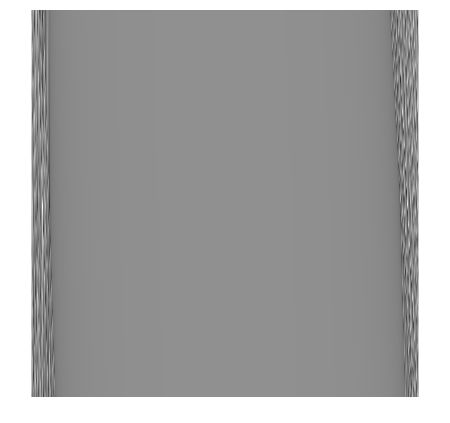

imwrite(R, 'filtered back.png')
imwrite(F, 'fan_filtered_backprojection.png')
imwrite(I, 'sinogram.png')

imshow(R, [])

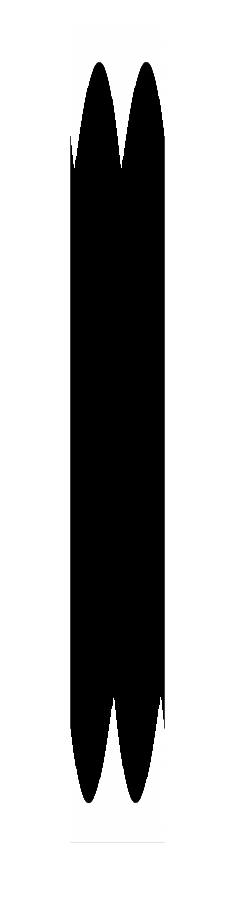

imshow(I, [])